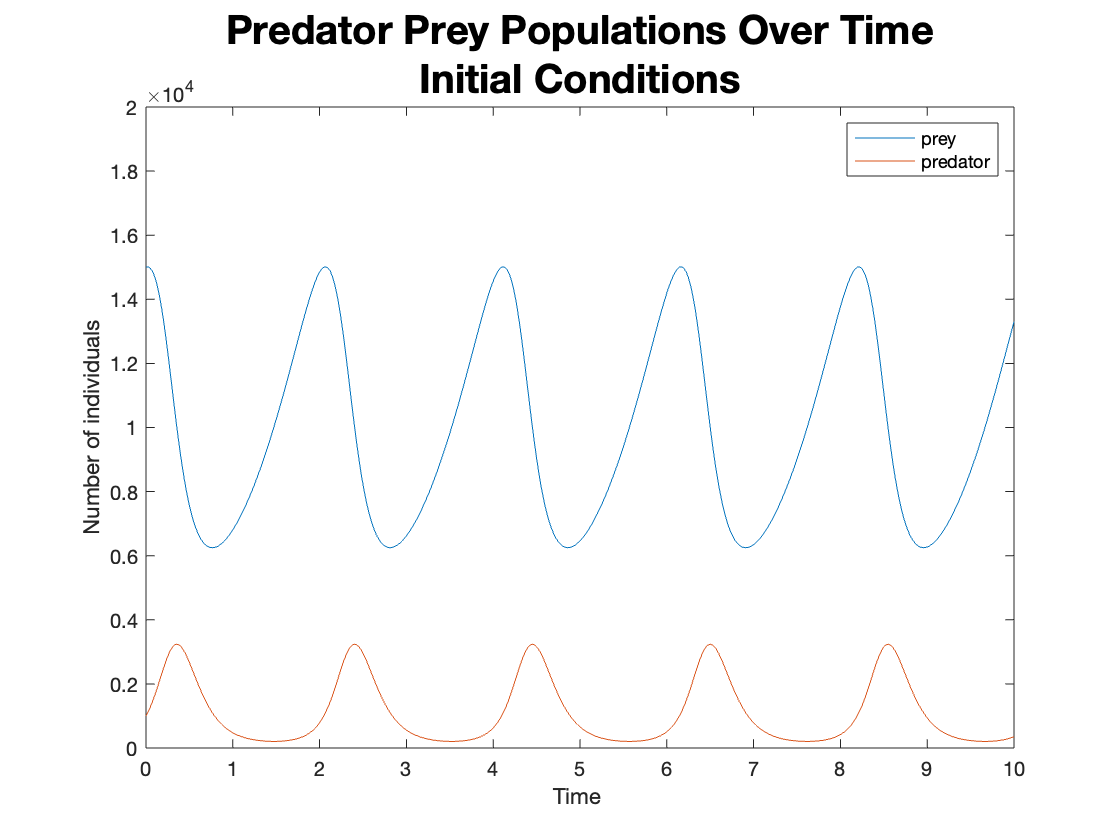

% SysMIC Miniproject: Modelling Predator-Prey Interactions
% November 2022 Cohort
% Copyright 2023 Spas Getov

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MATLAB SCRIPT FOR LOTKA-VOLTERRA MODEL SIMULATION
% This script will set up the parameters and intial conditions
% for prey (hare) and predator (lynx) populations in a 
% predator-prey model.

% The background and justification for using the methodology here
% is further discussed in the MiniprojectReprot.docx document
% accompanying this script file. As shown in section III of this
% accompanying document the Lotka-Volterra (LV) predator-prey
% model can be described using two coupled defferential equations:

%    dX/dt = (k1*X) - (k2*X*Y)    and    dY/dt = (k2*X*Y) - (k3*Y)

% where X represents the prey species, Y represents the predator
% species, and k1/k2/k3 represent three rate constants that
% determine the dynamics of predator-prey interactions.

% A solution for the above differential equations is implemented
% below, allowing simulations using different predator/prey
% population numbers and different rate constants to then be run,
% and the simulation results to be plotted and subsequently
% compared with real-world data.
% 
% The two LV differential equations are defined in the model_LV1 
% function at the bottom of this script file and the ode45 
% function is used  to solve the quations and run the simulation. 
% 
% ode45 is an inbuilt MATLAB function for the numerical solution 
% of ordinary differential equations using variable step size 
% Runge-Kutta integration methods. ode45 uses a 4th and 5th order 
% pair of formulas for high accuracy
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Initial Settings
%-----------------
options = odeset('InitialStep', 0.1,'MaxStep', 0.1); %options for integration algorithm used in ode45 function
t_range= [0 10];    % Setting limits of timeperiod studied

x_ini=[15000 1000]; % Initial populations of hare and lynx
k1= 1.1;            % Rate of hare (prey) birth
k2= 0.001;          % Rate of predation (lynx kills hare)
k3 = 10;            % Rate of lynx (predator) death

p = [k1 k2 k3];
% This vector is created to store the model paremeters. 
% These can then be passed to the model_LV1 function as well as to
% the ode45 function facilitating the running of simulations with
% different values for the parameters.



% Simulation
%--------------
[t,x]=ode45(@model_LV1,t_range,x_ini,options, p);

% Plot time series of all variables
figure(1);
clf
plot(t,x(:,:));
hold on
title({'Predator Prey Populations Over Time';'Initial Conditions'}, 'FontSize', 20)
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 20000])
legend('prey', 'predator', 'location', "northeast")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PART 1 - LOTKA-VOLTERRA MODEL EXPLORATION
% 
% 
%-----------------------------------------------
% Fnding steady states in the LV model
%-----------------------------------------------
% 
% Steady states will occur when the solutions of the two coupled LV
% differential equations are zero:
%
% 0 = (k1*X) - (k2*X*Y) and 0 == (k2*X*Y) - (k3*Y)
%
% These two equations are factorised and solved simulateneously below

syms X Y
[ssX ssY] = solve(X*(k1-k2*Y)==0,Y*(k2*X-k3)==0,X,Y)

$$ssX = \left(\begin{array}{c} 0\\ 10000 \end{array}\right)$$

$$ssY = \left(\begin{array}{c} 0\\ 1100 \end{array}\right)$$

ssX = double(ssX)

ssX =            0
       10000


ssY = double(ssY)

ssY =            0
        1100


% Both X (hare) and Y (lynx) have steady states at 0 which means
% if there are no animals nothing happens so this is trivial
% But also ssX = 10000 and ssY = 1100 gives the steady states around
% which the model oscillates; these can be displayed graphically

figure(1)
yline(ssX(2), '-.b', 'DisplayName', 'preySS')

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 10000
            Color: [0 0 1]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: ''
      DisplayName: 'preySS'

  Show all properties


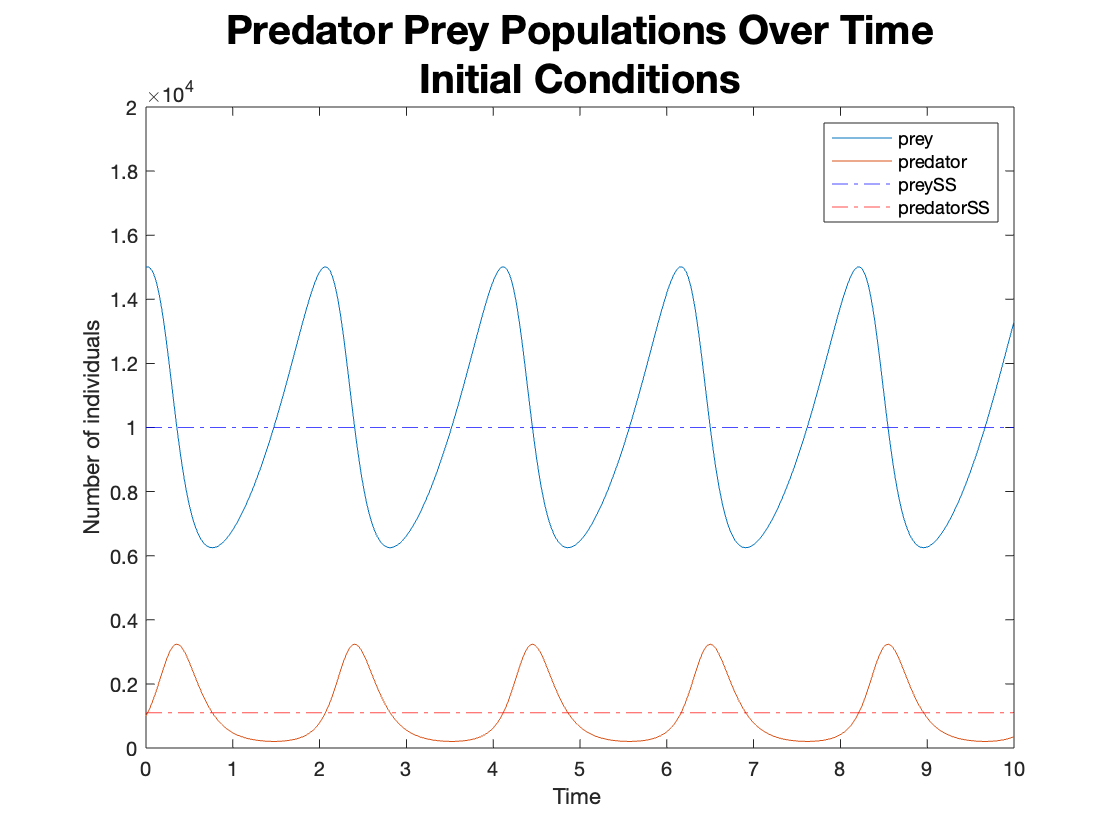

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 1100
            Color: [1 0 0]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: ''
      DisplayName: 'predatorSS'

  Show all properties


yline(ssY(2), '-.r', 'DisplayName', 'predatorSS')

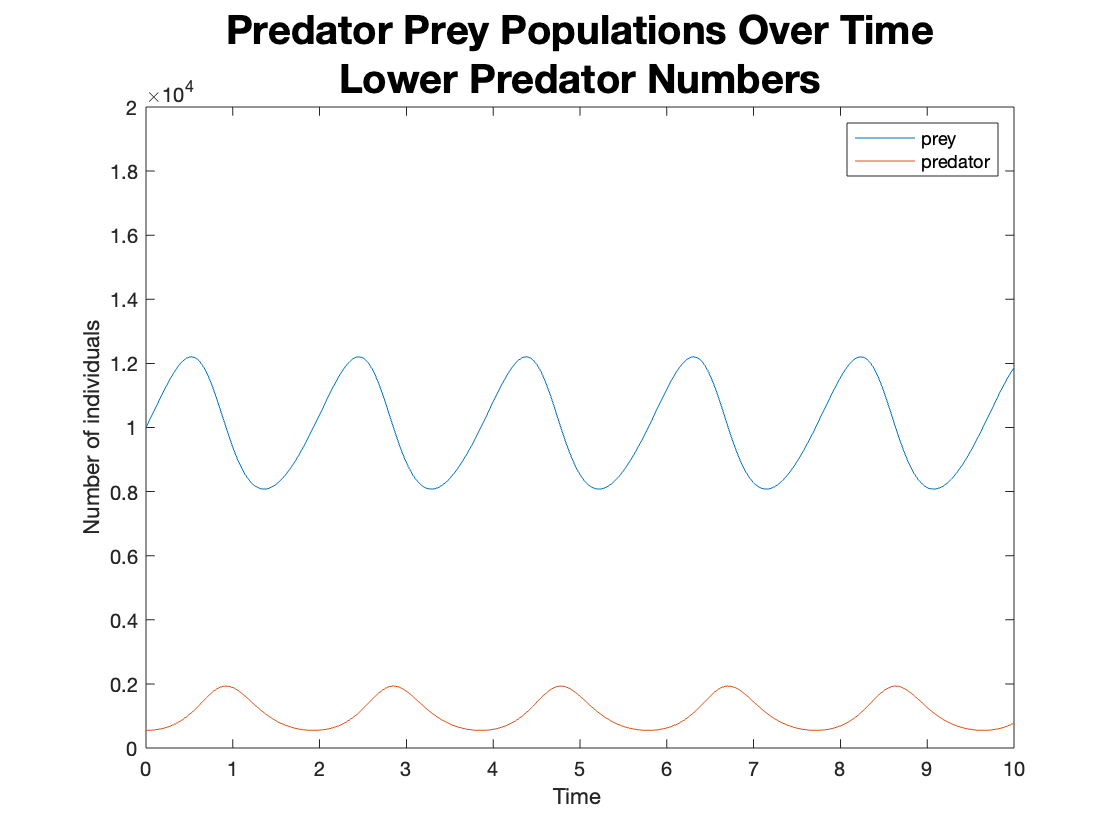

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Investigating impact of moving away from steady state population values
%----------------------------------------------------

%1) decreasing predator numbers below steady state
x_ini2 = [10000 550];

% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini2,options, p);
% Plot time series of all variables
figure(2);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Lower Predator Numbers'}, 'FontSize', 20)
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 20000])
legend('prey', 'predator', 'location', "northeast")


% Decreasing predator numbers below the steady state produces periodic
% oscillations in both predator and prey populations. The furter predator
% numbers are decreased the larger the amplitude of the oscillations
% (bigger changes of population size) but the frequency of oscillations
% remains the same with a full cycle occurring approximately every two
% years for both species.

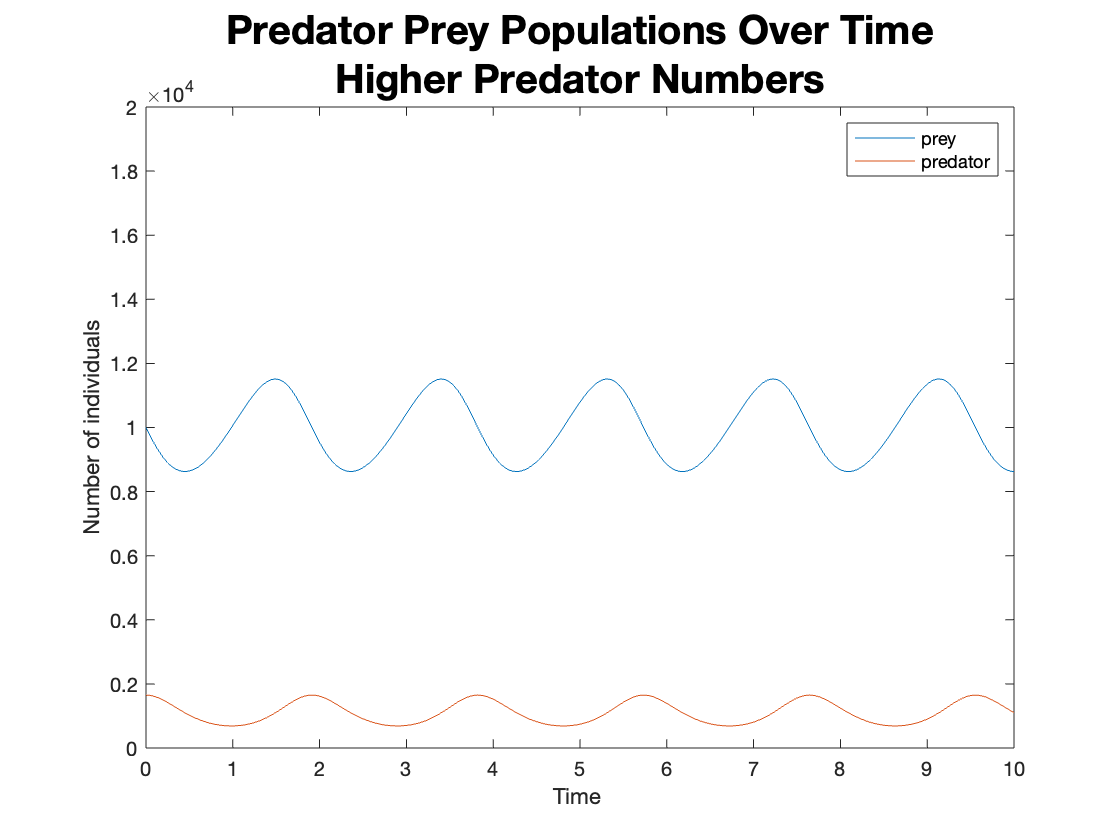

%2) increasing predator numbers above steady state by an equivalent amount 
% to section 1)
x_ini3 = [10000 1650];

% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini3,options, p);
% Plot time series of all variables
figure(3);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Higher Predator Numbers'}, 'FontSize', 20)
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 20000])
legend('prey', 'predator', 'location', "northeast")


% Increasing, rather than decreasing, predator numbers (going above the
% steady state) again produces oscillations every two years approximately
% and again the larger the increase, the bigger the amplitude of the
% oscillations. The oscillations are in antiphase compared to those 
% produced by a decrease from the stead state (section 1). This makes sense
% since increasing predator population causes prey numbers to initially fall
% (compared to the steady state) whereas decreasing predator population
% allows prey numbers to initially rise.

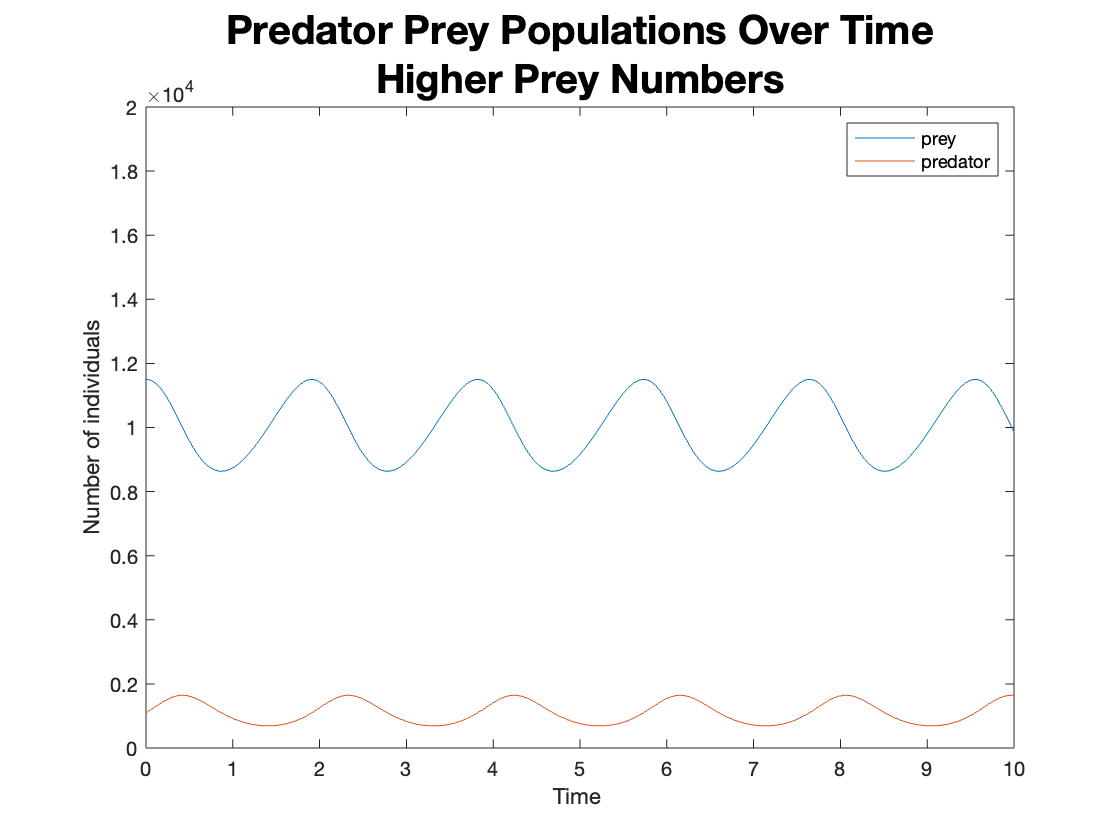

%3) increasing prey above steady state equivalent amount to section 2)
x_ini4 = [11500 1100];

% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini4,options, p);
% Plot time series of all variables
figure(4);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Higher Prey Numbers'}, 'FontSize', 20)
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 20000])
legend('prey', 'predator', 'location', "northeast")


% Increasing prey numbers above the steady state population size has
% a very similar effect to increasing predator numbers (section 2).
% There are again oscillations in populations of both species every
% couple of years. The main difference is that prey numbers start at
% a higher value than in the previous example so it takes longer for
% predation to bring them down (i.e. the plot is shifted rightwards).

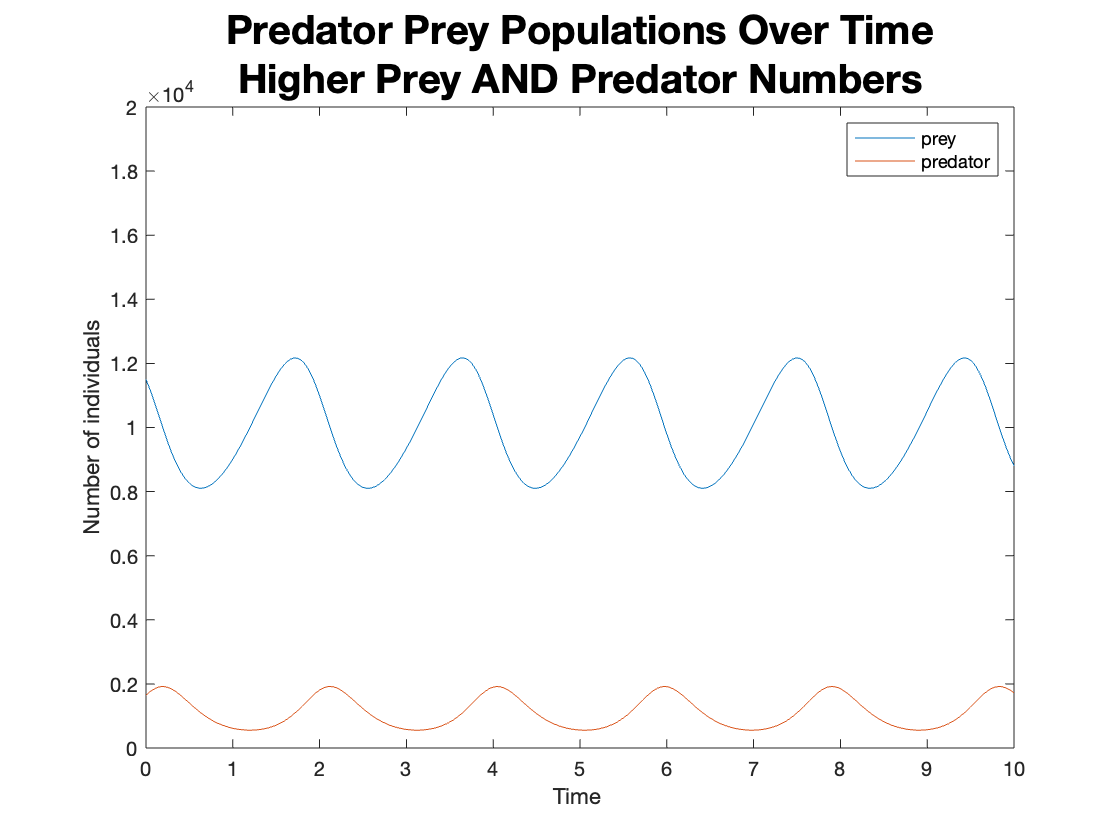

%4) increasing prey AND predators above steady
x_ini6 = [11500 1650];

% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini6,options, p);
% Plot time series of all variables
figure(4);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Higher Prey AND Predator Numbers'}, 'FontSize', 20)
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 20000])
legend('prey', 'predator', 'location', "northeast")


% If an increase in predator population away from the steady state
% occurs simultaneously to the increase in prey population modelled
% in section 3 above, the plot shifts slightly leftward again (the
% initial prey population falls more quickly with increased predation)
% and the overall size of the oscillation is larger both for predators
% (since numbers have been increased) and for prey (presumably since
% increased predator numbers drive the prey population lower before
% there is sufficient drop in predator numbers to allow prey population
% to begin recovering).

% Overall, the four investigative adjsutments in starting predator
% and prey numbers above seem to show that:

% - Moving away from the steady state populations causes
% regular oscillations in predator and prey numbers.

% - The larger the deviation of initial numbers (of either
% predator or prey) from the steady state, the larger the
% amplitudes of oscillations in both predator and prey populations

% - Changing either predator or prey numbers away from their respective
% steady state seems to have the same effect but in this model we need 
% to change prey numbers by about 1/3 as much as predator numbers, 
% relative to the steady state populations, in order  to have the same 
% effect on oscillation amplitude. E.g. if predator predator numbers go
% 110 above the steady state of 1100 (10% increase) then prey numbers
% would need to go up ~300 above the steady state of 10000 (around 3% 
% increase) for a similar effect size. This difference can be adjusted
% using the rate constants (see below).

% - The frequency of oscillations is not affected by starting
% predator/prey numbers presumably because this freuqency is
% determined by the rate constants (see below).

% - The phase of oscillations is determined by the relative sizes
% of predator and prey populations at the start of the simulation.
% If the predator population is relatively high, the prey population 
% will decrease at the outset and vice versa.


% For some reason going down by 50% on predator numbers creates slighlty 
% bigger prey number oscillations than going up by 50% on predators. 
% I am not sure why this is. Is it because the effect of predator death
% (k3), if kept constant, is proportionately smaller for larger predator
% populations?

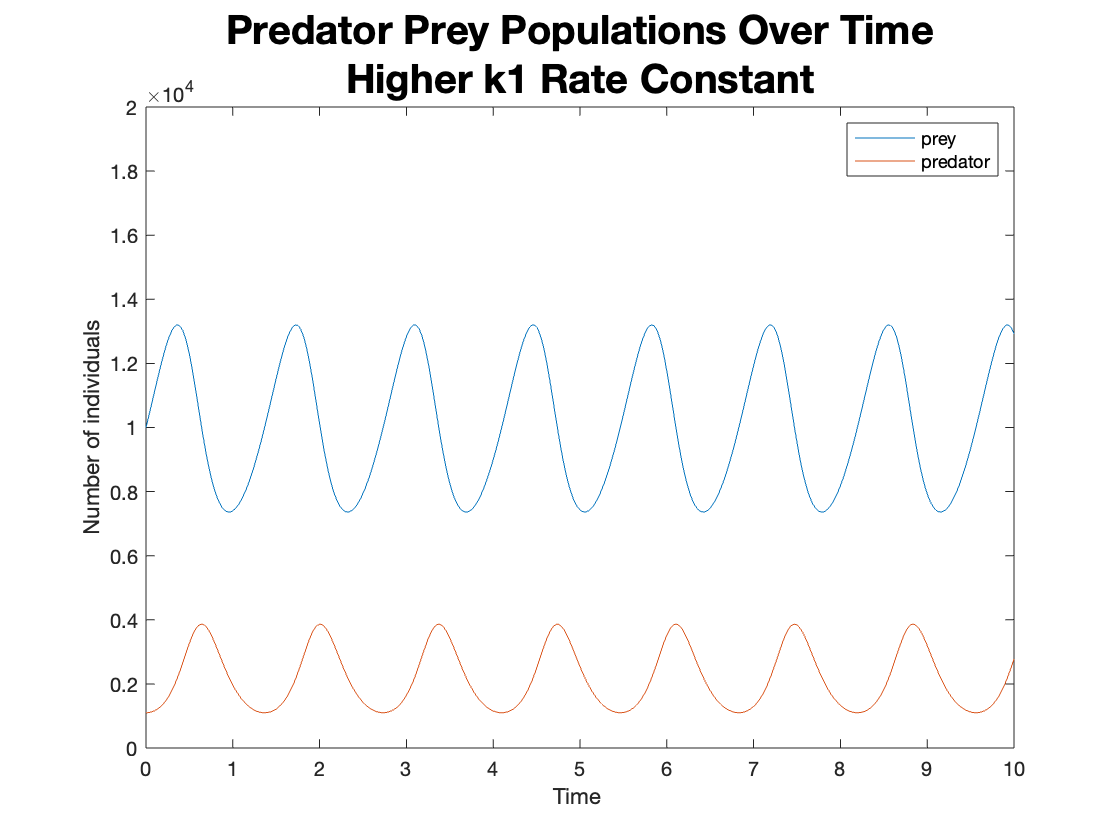

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Investigating impact of altering rate constants
%-----------------------------------------------------

% 1) altering k1 (rate of prey birth). Example of increasing k1

x_ini_ss = [10000 1100];

k1= 2.2;          % Rate of hare (prey) birth
k2= 0.001;          % Rate of predation (lynx kills hare)
k3 = 10;           % Rate of lynx (predator) death
p = [k1 k2 k3];

% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini_ss,options, p);
% Plot time series of all variables
figure(1);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Higher k1 Rate Constant'}, 'FontSize', 20)
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 20000])
legend('prey', 'predator', 'location', "northeast")


% reducing k1 below the value for which the steady state was
% found increases the amplitude of oscillations but decreases
% the frequency. Increasing k1 increases the amplitude but in
% this case also increases the frequency.

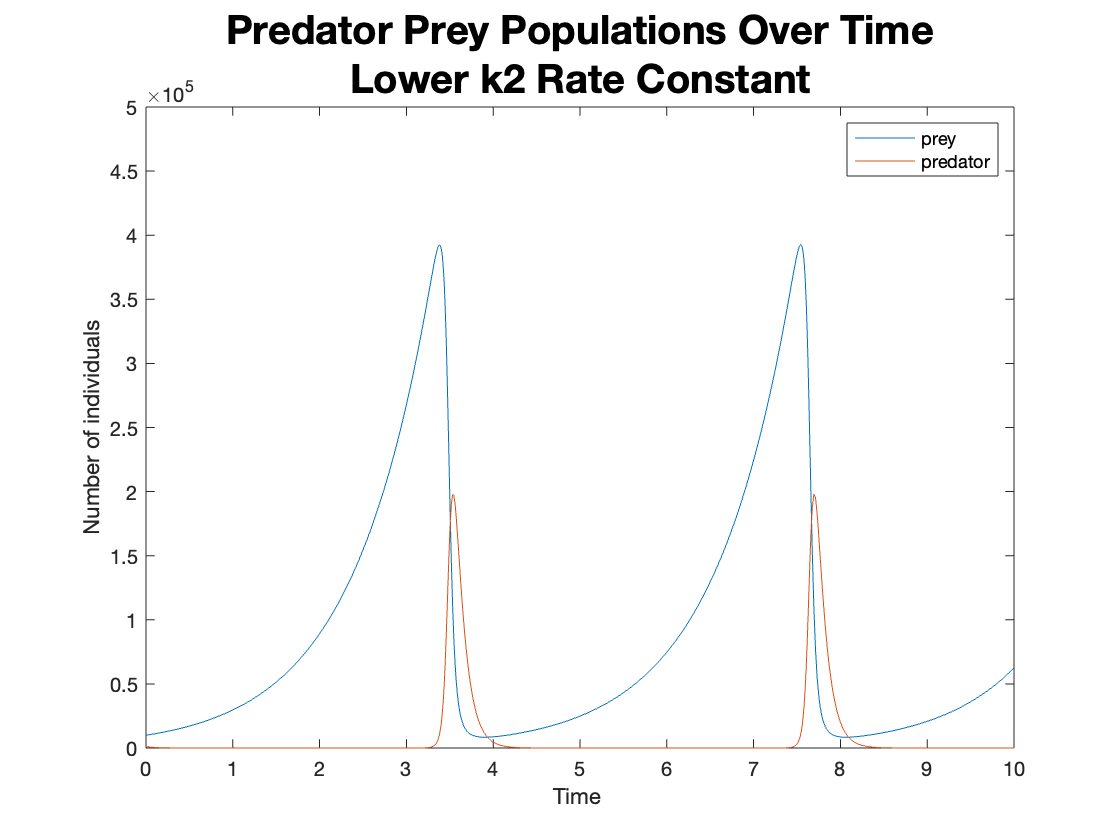


% 2) altering k2 (rate of predation). Example of decreasing k2

x_ini_ss = [10000 1100];

k1= 1.1;          % Rate of hare (prey) birth
k2= 0.0001;         % Rate of predation (lynx kills hare)
k3 = 10;           % Rate of lynx (predator) death
p = [k1 k2 k3];

% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini_ss,options, p);
% Plot time series of all variables
figure(1);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Lower k2 Rate Constant'}, 'FontSize', 20)
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 500000])
legend('prey', 'predator', 'location', "northeast")


% As k2 (predation rate constant) becomes higher than the value for 
% which there is a steady state the amplitude of oscillations in 
% predator numbers increases and the frequency of oscillations
% decreases. With a higher rate of predation it is expected that
% it woud take longer for prey numbers to build up, hence the lower
% frequency of oscillations.

% As the value of k2 goes further and further below the
% steady state value the amplitude of all oscillations increases and
% the frequency of all oscillations decreases. In addition, the shape
% of the oscillations changes (the peaks become narrower with steeper
% drop off especially for prey populations). If rate of predation is
% lower it makes sense that prey numbers can get higher, although it
% is not clear why they drop off so quickly. The reason frequency
% of oscillations gets lower is probably as rate of predation also
% relates to predator population growth in this model. If predators
% increase in numbers more slowly, the oscillations in population
% size would happen less frequently.

% Note scale of y axis has been changed due to increased amplitude of
% oscillations


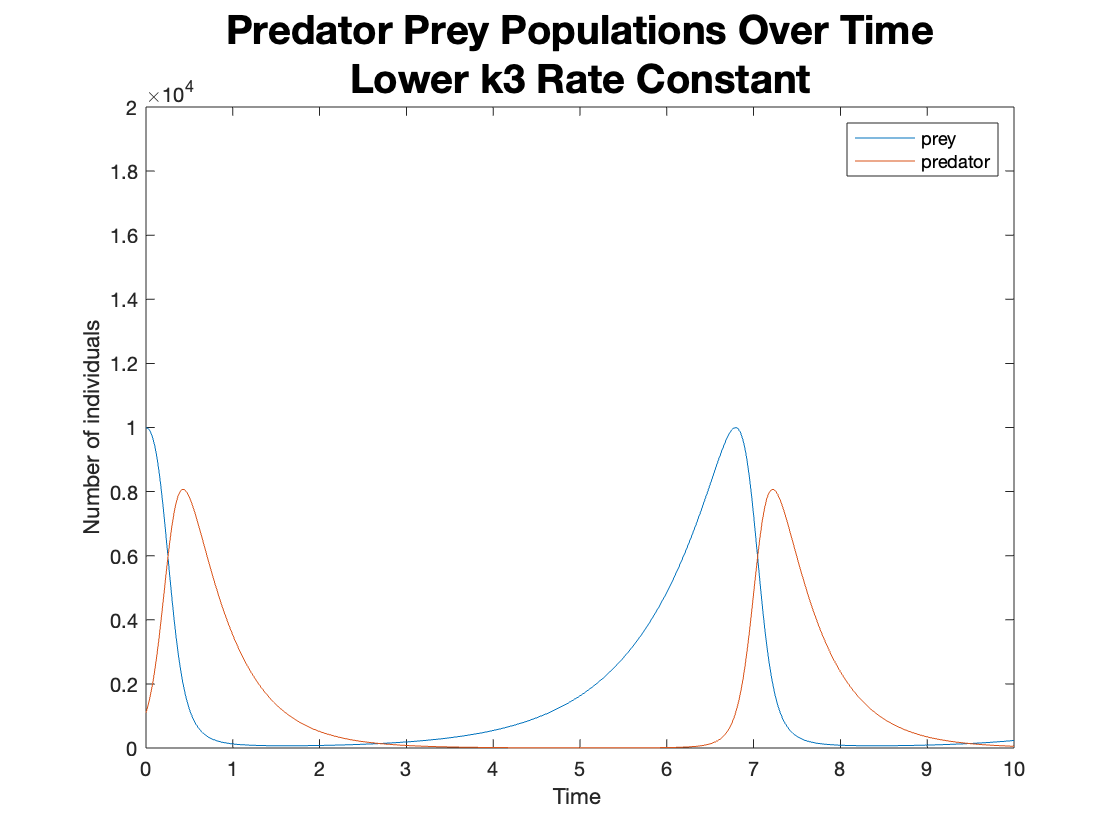

% 3) altering k3 (rate of predator death). Example of decreasing k3

x_ini_ss = [10000 1100];

k1= 1.1;          % Rate of hare (prey) birth
k2= 0.001;        % Rate of predation (lynx kills hare)
k3 = 2;           % Rate of lynx (predator) death
p = [k1 k2 k3];

% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini_ss,options, p);
% Plot time series of all variables
figure(1);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Lower k3 Rate Constant'}, 'FontSize', 20)
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 20000])
legend('prey', 'predator', 'location', "northeast")


% Reducing k3 means predators decay in number more slowly after peaking
% so get fewer cylces per unit time. Increasing k3 leads to very narrow
% peaks in predator population as they die off quickly after prey numbers
% drop. Also takes predator population longer to respond to increase in 
% prey numbers. When k3 is below 1 the peak predator populations become 
% higher than peak prey populations

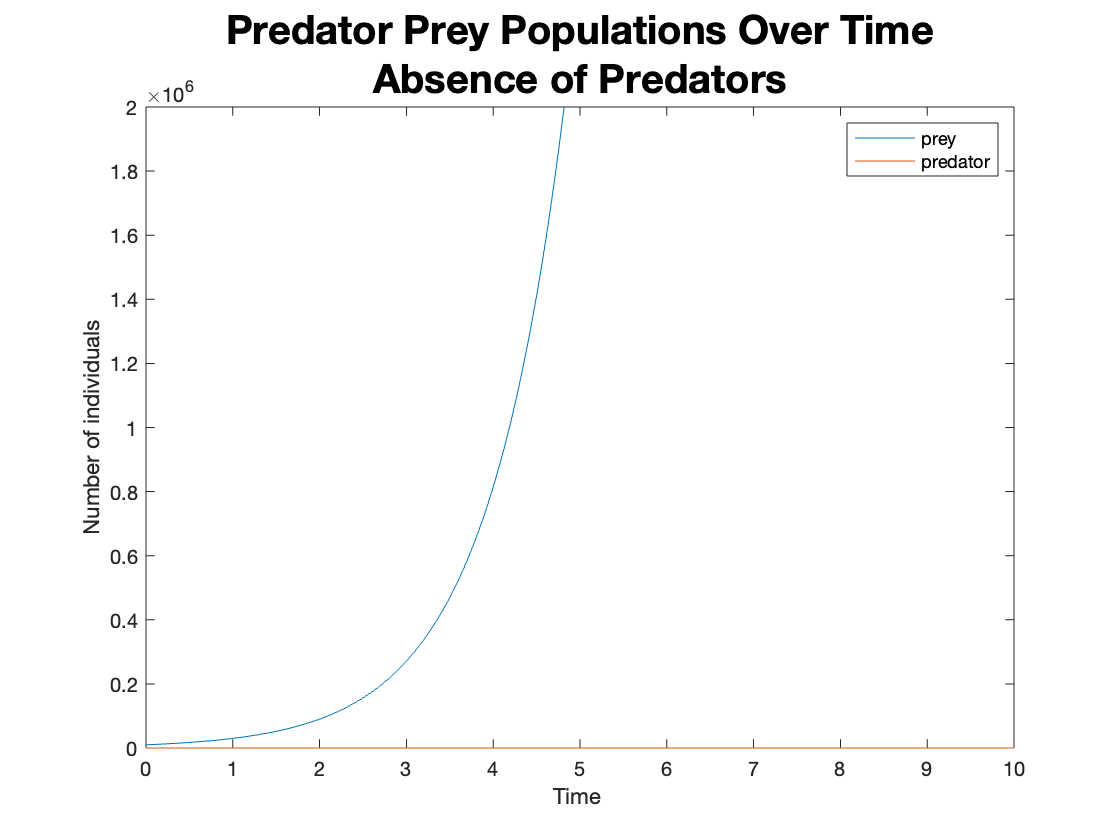

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PART 2 - FITTINGT THE LV MODEL TO REAL-WORLD HARE-LYNX DATA
% 
% 
%-----------------------------------------------
%Show hare population without predators exhibits exponential growth

x_ini5 = [10000 0];

k1= 1.1;          % Rate of hare (prey) birth
k2= 0.001;          % Rate of predation (lynx kills hare)
k3 = 10;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range,x_ini5,options, p);
% Plot time series of all variables
figure(5);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Absence of Predators'}, 'FontSize', 20)
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 2000000])
legend('prey', 'predator', 'location', "northeast")


%Added a couple of zeros to y_lim to see the plot better

% Find a biologically plausible value of k1 from the exponential 
% growth equation  X(t)=X0*exp(k1*t), where X0 is the initial hare
% populaiton, X(t) is the hare population at time t and k1 is the
% rate of hare birth, as previously.
%---------------------------------------------------------------

% X0 could be 2 (the lowest possible number of hares that could breed)
% According to the literature (https://www.nps.gov/articles/snowshoe-hare.htm)
% snowshoe hares produce anywhere from 4 - 12 young (leverets) each year.
% This occurs in 2-3 breeding periods with 2-4 young in each period.
 

% So t should be 1 (a year), X0 should be 2 and X(t) should be 10 (mean of
% 8 offspring (leverets) in a year plus the two parents).

syms k1rw
k1r = solve(10 == 2*exp(k1rw), k1rw)

$$k1r = \log\left(5\right)$$

k1r = double(k1r)

k1r = 1.6094


% Note, this calculation makes the following big assumptions, which are
% discussed further in the study report document MiniprojectReprot.docx:

% 1) None of the hares die. Otherwise k1 would need to be calculated
% as k(birth) minus k(death). In practice if we were accounting for hare 
% death the k1 would be lower than what we have calculated above.

% 2) The effects of predation (other rate constnats), scarcity of food,
% scarcity of space and other natural phenomena (e.g. poor weather) are
% ignored

% 3) It is assumed that hares are able to reproduce as soon as they are
% born (the fact they need to reach sexual maturity before reproducing
% is not accounted for).

% Estimate steady states from the supplied fur pelt data
%-------------------------------------------------------

% Based on the plotted fur pelt numbers (from Hudson Bay Company records),
% found in the miniproject guidelines, can estimate steady states:

% Hare 5000, lynx 3200

% using above estimate for k1r can rearrange the differential equations
% to estimate k2r and k3r when X and Y are at steady state (Xssr and Yssr):

% 0 = (k1r*Xssr) - (k2r*Xssr*Yssr) ->   k1r*Xssr = k2r*Xssr*Yssr ->
%                                       k1r =k2r*Yssr
%                                       k1r/Yssr = k2r


% 0 == (k2r*Xssr*Yssr) - (k3r*Yssr) ->  k2r*Xssr*Yssr = k3r*Yssr
%                                       k2r*Xssr = k3r
% sub in above solution of k2r      ->  k1r/Yssr*Xssr = k3r

% so we have:
% k2r = k1r/Yssr
% k3r = k1r*(Xssr/Yssr)

Xssr = 5000;
Yssr = 3200;

k2r = k1r / Yssr

k2r = 5.0295e-04

k3r = k1r * (Xssr/Yssr)

k3r = 2.5147

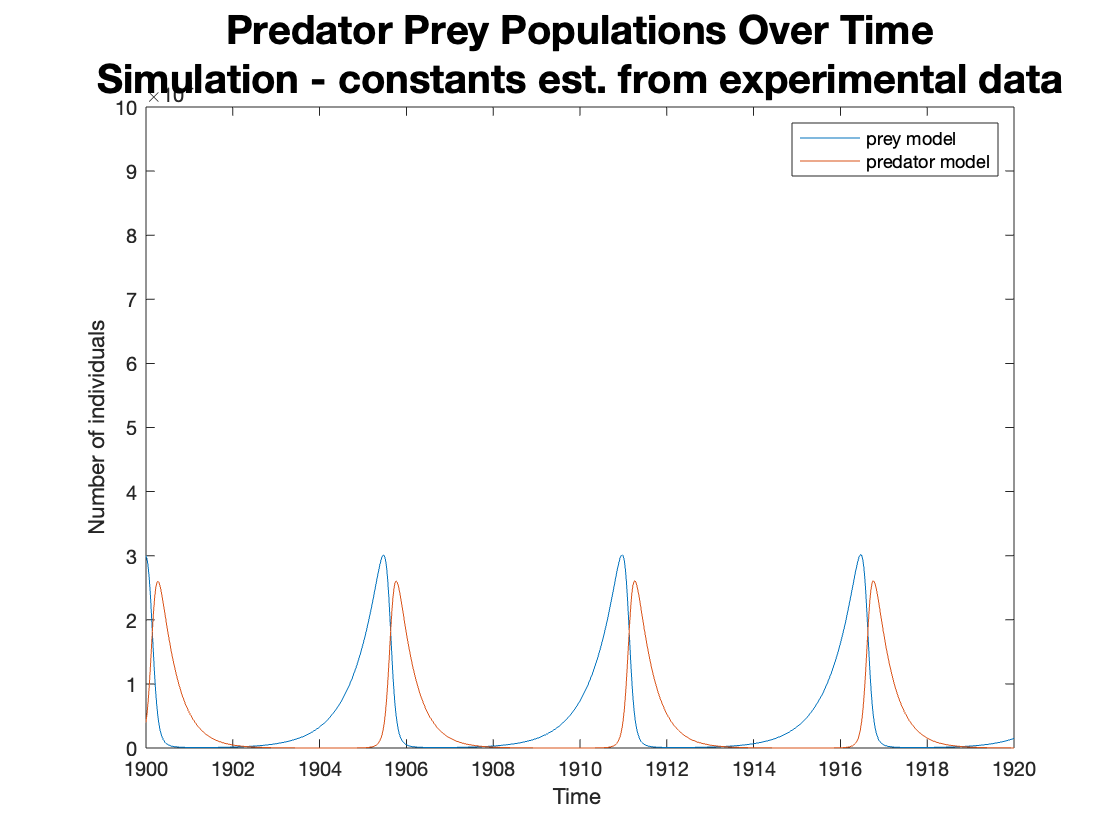

% Run simulation using rate constants newly derived from real-world data,
% using historical records from 1900 for srarting populations
%------------------------------------------------------------------

t_range_r = [1900 1920];
x_ini_r = [30000 4000];

k1= 1.6;              % Rate of hare (prey) birth
k2= 0.0005;           % Rate of predation (lynx kills hare)
k3 = 2.5;             % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(6);
clf
plot(t,x(:,:));
title({'Predator Prey Populations Over Time';'Simulation - constants est. from experimental data'}, 'FontSize', 20)
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")

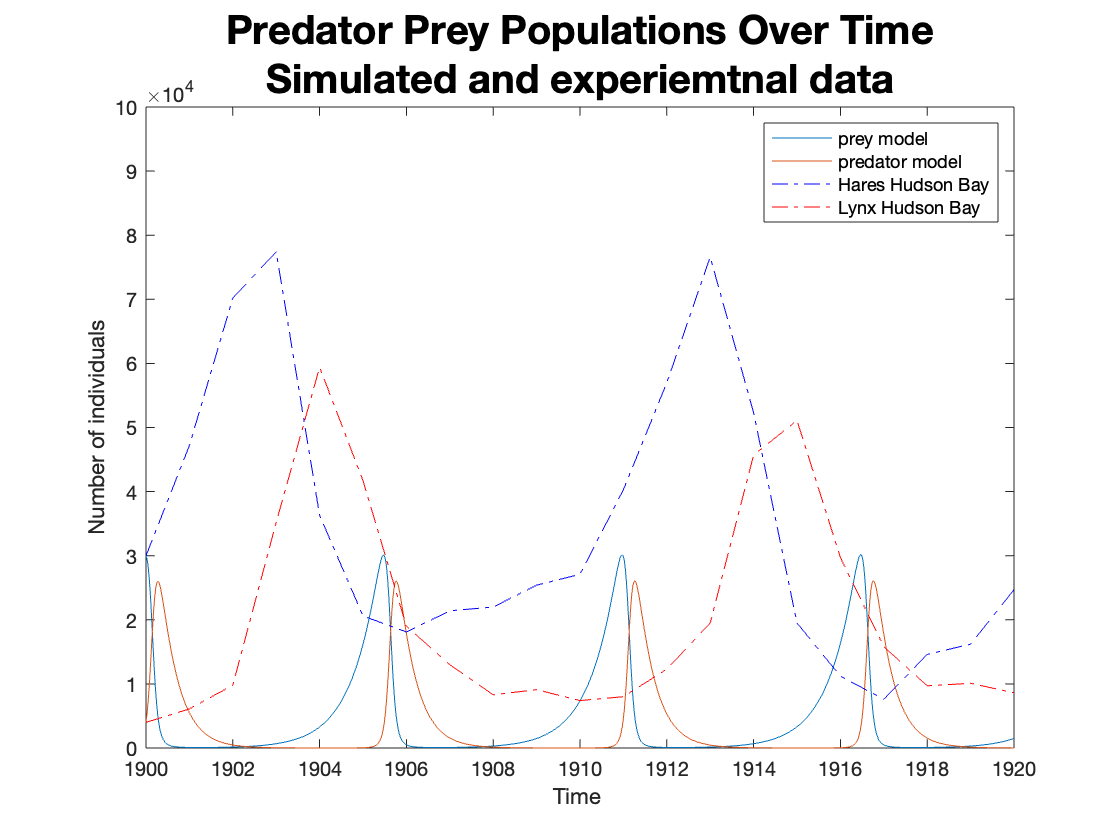

% Overlay the real-world histroical fur pelt data onto previous figure
%--------------------------------------------------------------------

T = readtable('Fur_Pelts_1900_to_1920.csv');
%reads table and automatically detects and skips header
%Can also specify 'NumHeaderLines', 3 or whatever in extra argument
%can also use csvimport
T = table2array(T);

plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated and experiemtnal data'}, 'FontSize', 20)



% The model-derived simulated data do not currently fit the real-world 
% data very well (oscillations too frequent, peaks too narrow and too 
% low in amplitude). We can try improve the fit in a systematic way
% by adjusting rate constants using the understanding of their effects,
% based on previous investigations described above.

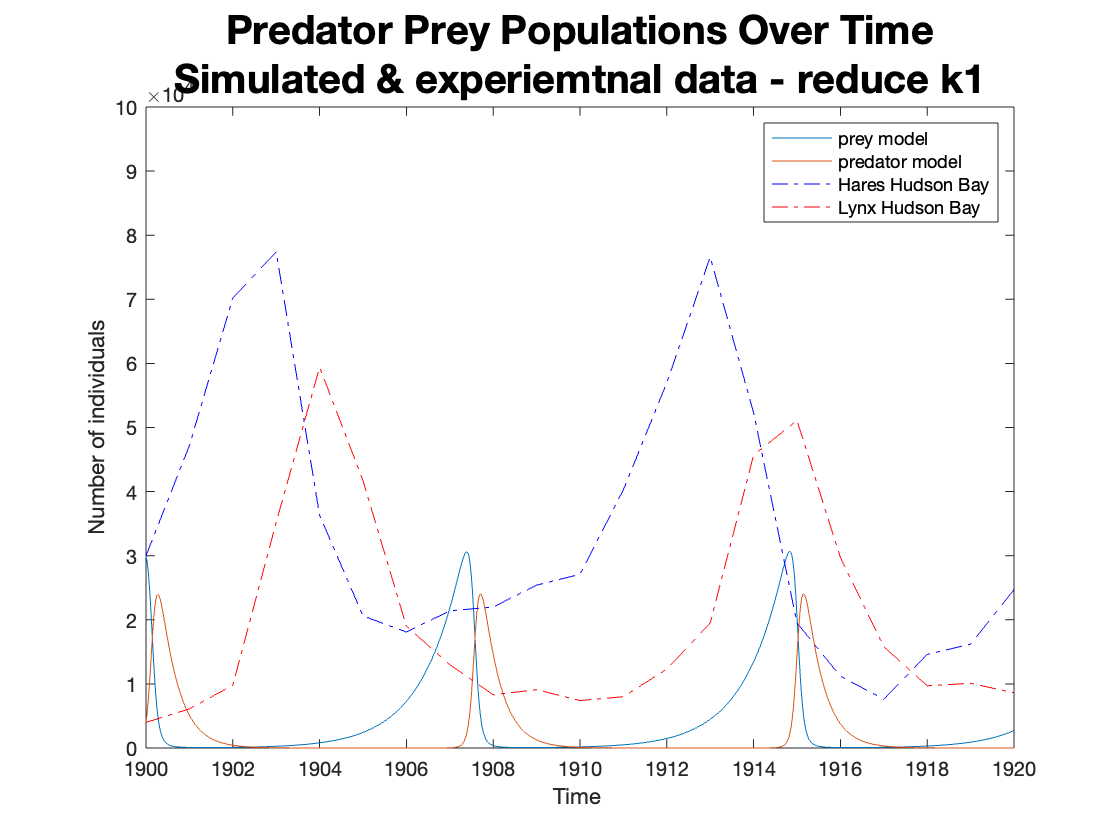

% 1) The oscillations are too frequent and low in amplitude in the 
% simulated data. Based on what we learned in previous sections could 
% reduce k1

k1= 1.1;          % Rate of hare (prey) birth
k2= 0.0005;          % Rate of predation (lynx kills hare)
k3 = 2.5;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(7);
clf
plot(t,x(:,:));
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")
plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated & experiemtnal data - reduce k1'}, 'FontSize', 20)
hold off


% Oscillation frequeny now more similar to real-world data but
% amplitude still too low.

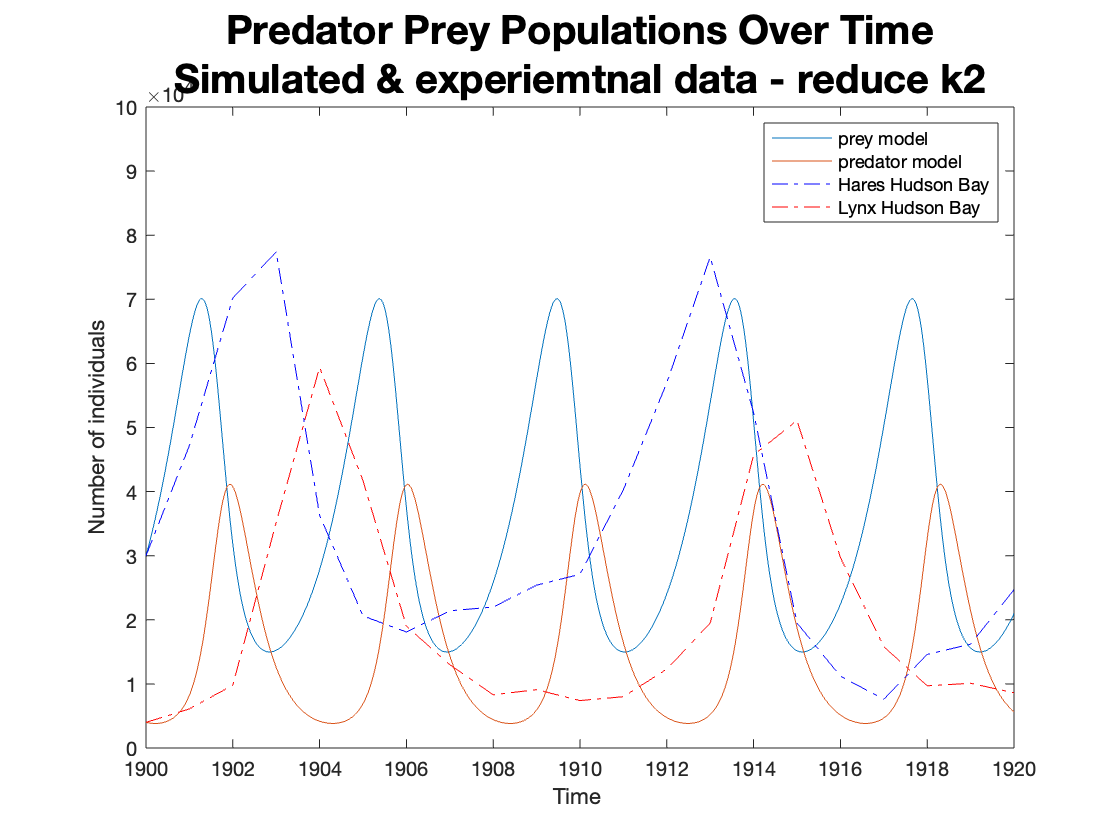

%2) Try reducing value of k2 to get increased oscillation amplitude

k1= 1.1;            % Rate of hare (prey) birth
k2= 0.00007;        % Rate of predation (lynx kills hare)
k3 = 2.5;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(7);
clf
plot(t,x(:,:));
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")
plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated & experiemtnal data - reduce k2'}, 'FontSize', 20)
hold off


% Ampoltude now much closer to real-world data but frequency has become
% too high again.

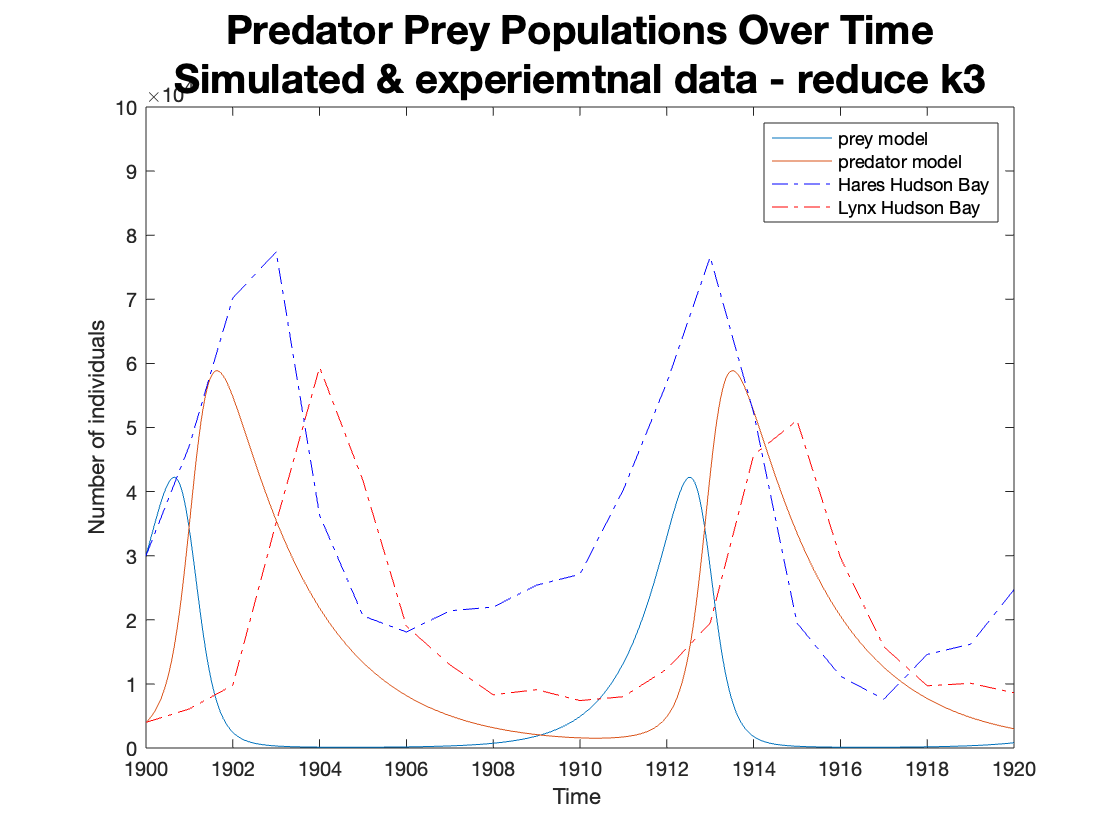

%3) Try reducing k3 (which should cause slower decay in predator 
% oscillations so should reduce frequency of population osciallations

k1= 1.1;            % Rate of hare (prey) birth
k2= 0.00007;        % Rate of predation (lynx kills hare)
k3 = 0.5;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(7);
clf
plot(t,x(:,:));
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")
plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated & experiemtnal data - reduce k3'}, 'FontSize', 20)
hold off


% The model is now a fairly good fit to the real-world data except that
% the initial population rise is too quick and prey numbers do not rise
% as high. The fit can be further optimised with more minor adjustment
% of the rate constants.

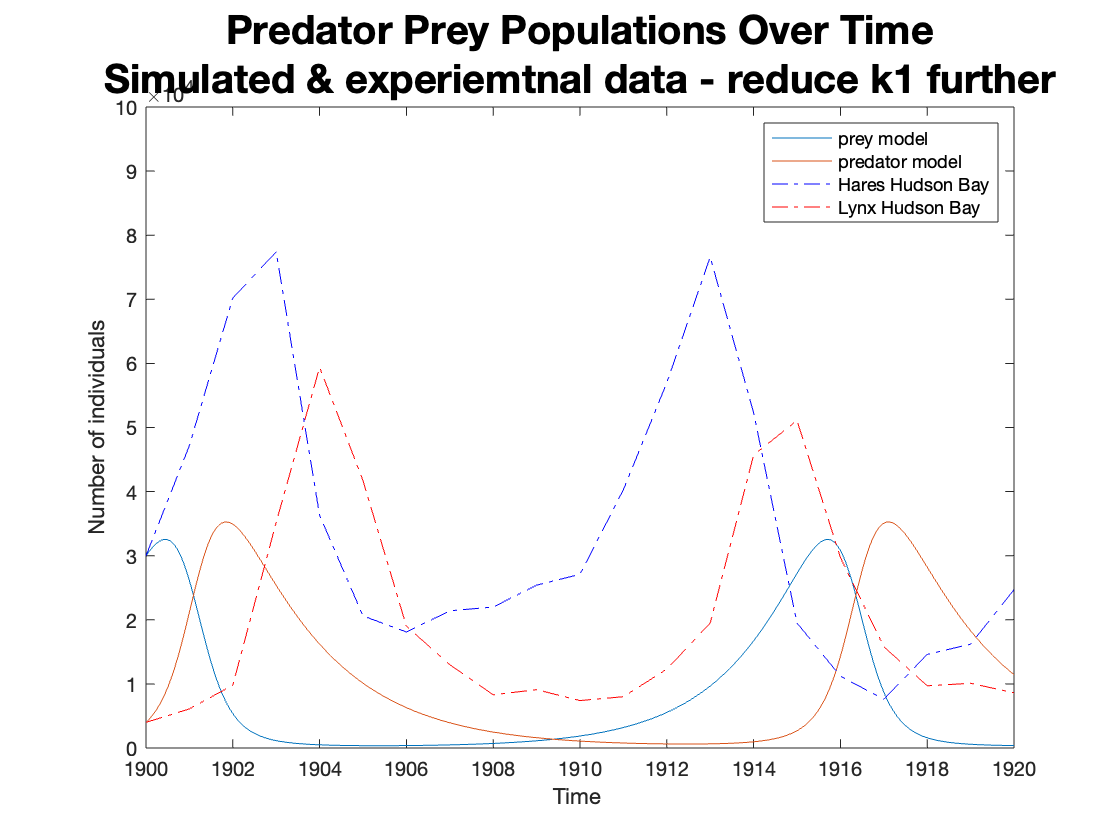

%4) Lowering k1 further gets prey oscillation amplitude closer to 
% predator oscillation amplitude

k1= 0.6;            % Rate of hare (prey) birth
k2= 0.00007;        % Rate of predation (lynx kills hare)
k3 = 0.5;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(7);
clf
plot(t,x(:,:));
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")
plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated & experiemtnal data - reduce k1 further'}, 'FontSize', 20)
hold off

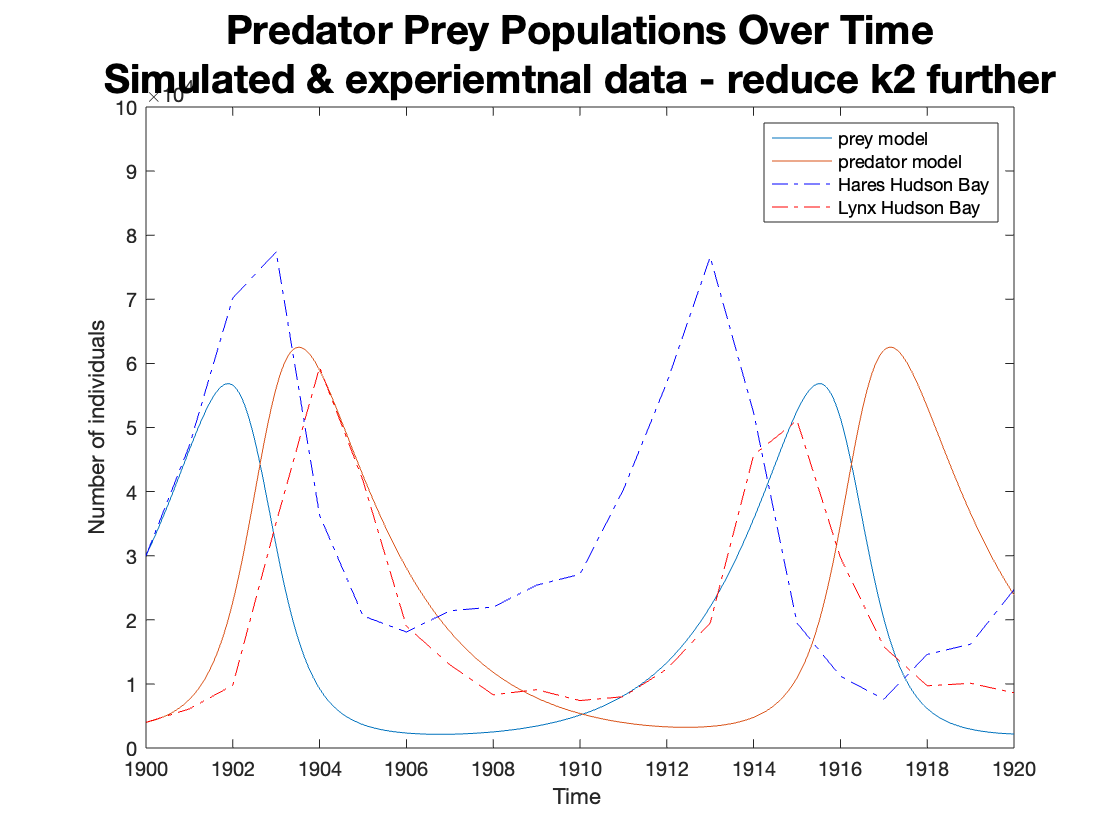

%5) Lowering k2 further (redcuing rate of predation) slows initial rise 
% of populations a bit and  allows populations to go higher overall.

k1= 0.6;            % Rate of hare (prey) birth
k2= 0.00003;        % Rate of predation (lynx kills hare)
k3 = 0.5;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(7);
clf
plot(t,x(:,:));
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")
plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated & experiemtnal data - reduce k2 further'}, 'FontSize', 20)
hold off

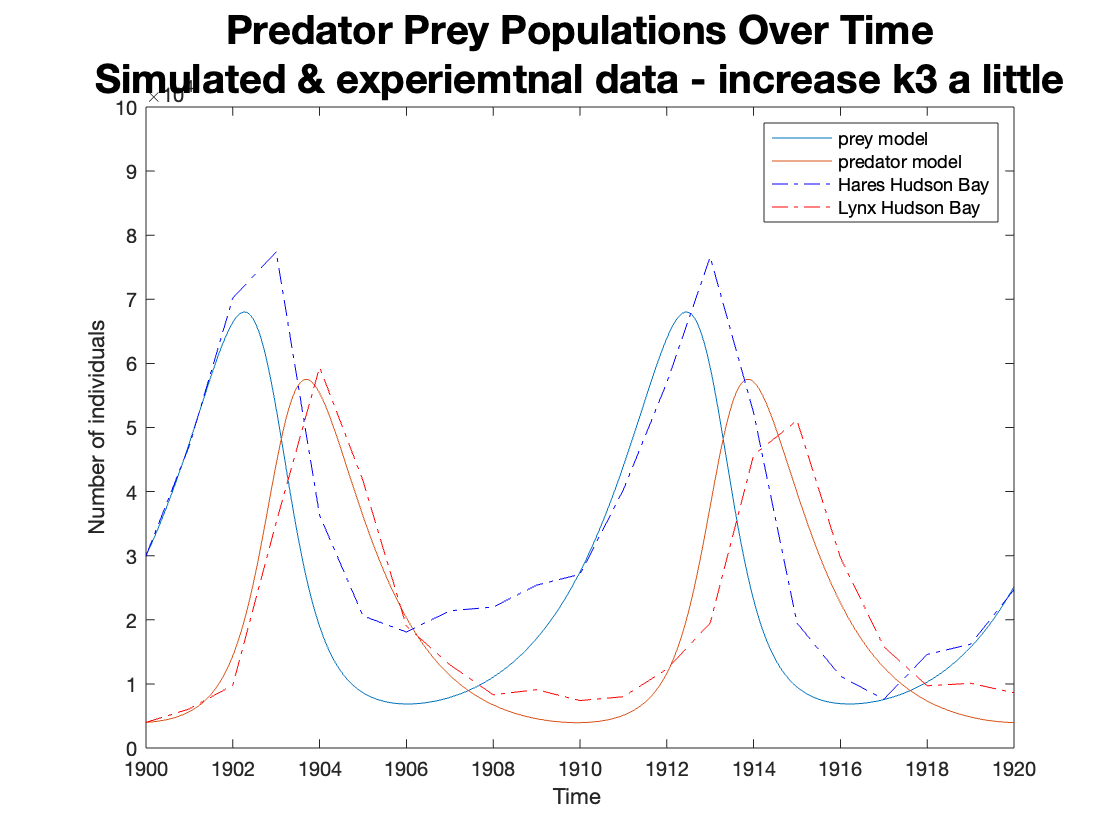

%6) Increating k3 a bit means predators die mroe quickly and this
% brings second oscillation in population numbers a bit sooner. This is
% now a very good fit to the real-world data.

k1= 0.6;            % Rate of hare (prey) birth
k2= 0.00003;        % Rate of predation (lynx kills hare)
k3 = 0.8;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(7);
clf
plot(t,x(:,:));
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")
plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated & experiemtnal data - increase k3 a little'}, 'FontSize', 20)
hold off

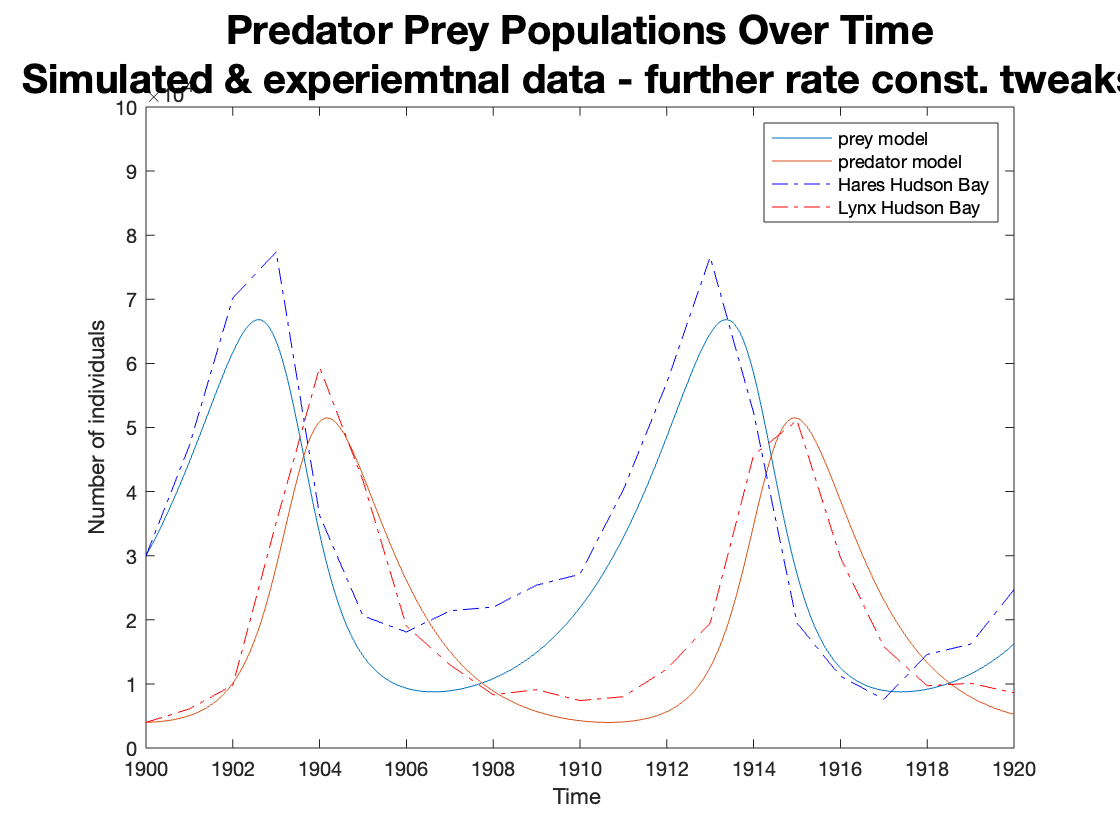

%7) Final tweaks to improve fit even further (lower k1 and k2 a little
%   more)

k1= 0.52;           % Rate of hare (prey) birth
k2= 0.000028;       % Rate of predation (lynx kills hare)
k3 = 0.8;           % Rate of lynx (predator) death
p = [k1 k2 k3];


% Simulation
[t,x]=ode45(@model_LV1,t_range_r,x_ini_r,options, p);
% Plot time series of all variables
figure(7);
clf
plot(t,x(:,:));
hold on
xlabel('Time ');
ylabel('Number of individuals');
ylim([0 100000])
legend('prey model', 'predator model', 'location', "northeast")
plot(T(:,1),T(:,2), '-.b', 'DisplayName', 'Hares Hudson Bay')
plot(T(:,1),T(:,3), '-.r', 'DisplayName', 'Lynx Hudson Bay')
title({'Predator Prey Populations Over Time';'Simulated & experiemtnal data - further rate const. tweaks'}, 'FontSize', 20)
hold off

function dxdt=model_LV1(t,x,p)
% The x and t input arguments are the outputs of the ode45
% function above and p are the rate cosntants.

% Initialize model vector with zeroes,
dxdt=zeros(2,1);
% Load parameter values from vector p
k1= p(1);   % Rate of hare (prey) birth
k2= p(2);   % Rate of predation (lynx kills hare)
k3 = p(3);  % Rate of lynx (predator) death


%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Coupled Differential Equations for LV model:
%
% dxdt (change in prey numbers over time)
dxdt(1)=  k1*x(1) - k2*x(1)*x(2);
% dydt (change in predator numbers over time)
dxdt(2)=   k2*x(1)*x(2) - k3*x(2);
%
end